
clear; clc;
Ts = 0.1; %Sampling time
% System 1: G1(s) = 10 / (s^3 + 5.8*s^2 + 8*s + 20)
G1 = tf(10, [1 5.8 8 20]);
G1_z = c2d(G1, Ts, 'tustin');
%disp(G1_z);

% System 2: G2(s) = (0.25 / (s^2 + 1.5*s + 0.5)) * exp(-s)

G2 = tf(0.25, [1 1.5 0.5], 'InputDelay', 1); 
G2_z = c2d(G2, Ts, 'tustin');

system = {G1_z, G2_z};
% Analyze System 1
fprintf('System 1: G1(s)\n');

System 1: G1(s)


% Poles
poles_G1 = pole(G1);
fprintf('Poles of G1: \n');

Poles of G1: 


disp(poles_G1);

  -5.0000 + 0.0000i
  -0.4000 + 1.9596i
  -0.4000 - 1.9596i



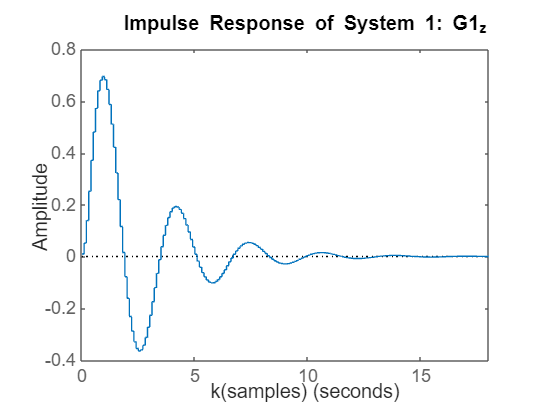


% Step response
figure;
step(G1_z);
title('Step Response of System 1: G1_z');
xlabel('k(samples)'); % X-axis label

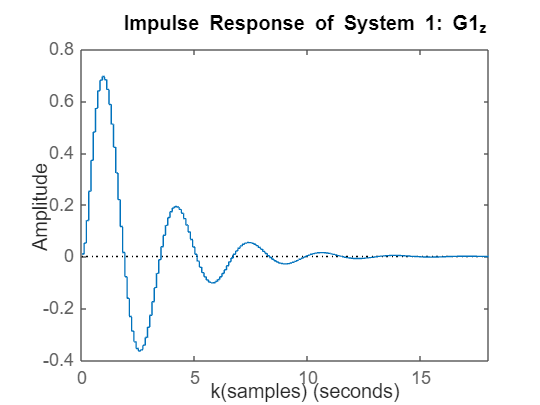

ylabel('Amplitude'); % Y-axis label

% Impulse response
figure;
impulse(G1_z);
title('Impulse Response of System 1: G1_z');
xlabel('k(samples)'); % X-axis label

ylabel('Amplitude'); % Y-axis label

% Bode diagram
%figure;
%bode(G1_z);
%title('Bode Diagram of System 1: G1_z');

%disp(G2_z);
% Analyze System 2
fprintf('System 2: G2(s)\n');

System 2: G2(s)


% Poles
poles_G2 = pole(G2);
fprintf('Poles of G2: \n');

Poles of G2: 


disp(poles_G2);

   -1.0000
   -0.5000



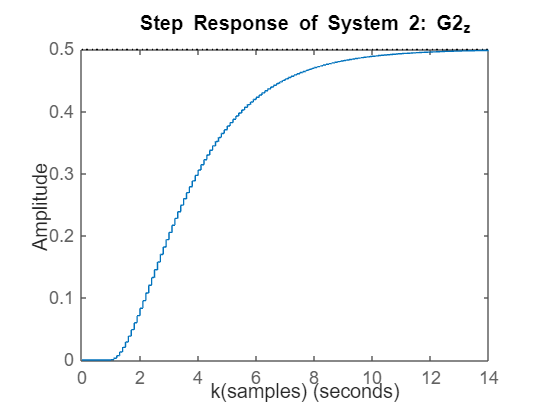


% Step response
figure;
step(G2_z);
title('Step Response of System 2: G2_z');
xlabel('k(samples)'); % X-axis label

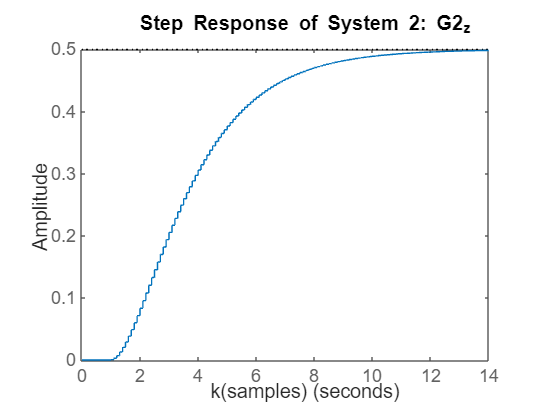

ylabel('Amplitude'); % Y-axis label

% Impulse response
figure;
impulse(G2_z);
title('Impulse Response of System 2: G2_z');
xlabel('k(samples)'); % X-axis label

ylabel('Amplitude'); % Y-axis label

% Bode diagram
%figure;
%bode(G2_z);
%title('Bode Diagram of System 2: G2_z');


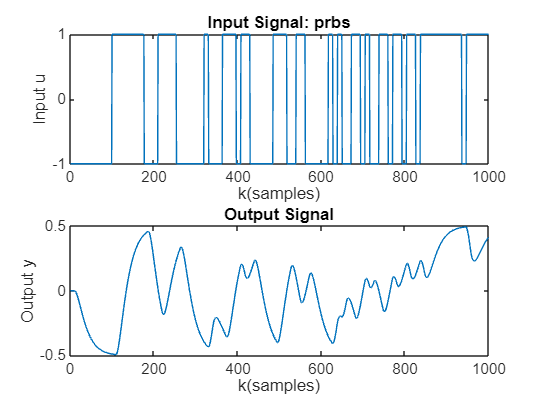


N = 1000;  % Number of samples
Sigma = 0.05;  % Standard deviation of noise
seed = 1;  % Random seed for reproducibility

% Generate dataset

[u, y, t] = generate_dataset(G2_z, 'prbs', Ts, N, Sigma, seed);


%disp(u);
%disp(y);


nk = 1; 
na = 3; 
nb = 3;

% Generate the regression matrix
X = arx(u, y, na, nb);
% Display the regression matrix
disp('Regression Matrix X:');

Regression Matrix X:


disp(X);

   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000         0         0         0
   -1.0000   -1.0000   -1.0000    0.0006         0         0
   -1.0000   -1.0000   -1.0000    0.0028    0.0006         0
   -1.0000   -1.0000   -1.0000    0.0071    0.0028    0.0006
   -1.0000   -1.0000   -1.0000    0.0130    0.0071    0.0028
   -1.0000   -1.0000   -1.0000    0.0204    0.0130    0.0071
   -1.0000   -1.0000   -1.0000    0.0289    0.0204    0.0130
   -1.0000   -1.0000   -1.0000    0.0385    0.0289    0.0204
   -1.0000   -1.0000   -1.0000    0.0489    0.0385    0.0289
   -1.0000   -1.0000   -

%disp(y);

% Estimating Paratmeters using Least squares method
y_arx = y(na+1:end);
% Least squares
theta = (X' * X ) \ (X' * y_arx);
%disp('Estimated Parameters:');
disp(theta);

   -0.0001
    0.0002
    0.0001
   -2.8775
    2.7752
   -0.8973



% Extract parameters
b = theta(1:na); % Input coefficients
a = theta(na+1:end); % Output coefficients
%disp(a);
%disp(b);

y_hat = recursive_arx(u, theta, na, nb, nk);
disp(y_hat)

         0
         0
         0
   -0.0002
   -0.0007
   -0.0018
   -0.0035
   -0.0058
   -0.0090
   -0.0130
   -0.0178
   -0.0235
   -0.0301
   -0.0374
   -0.0455
   -0.0543
   -0.0637
   -0.0737
   -0.0842
   -0.0950
   -0.1061
   -0.1175
   -0.1289
   -0.1404
   -0.1518
   -0.1632
   -0.1743
   -0.1852
   -0.1957
   -0.2059
   -0.2158
   -0.2252
   -0.2342
   -0.2428
   -0.2509
   -0.2585
   -0.2657
   -0.2725
   -0.2789
   -0.2849
   -0.2905
   -0.2958
   -0.3008
   -0.3055
   -0.3100
   -0.3143
   -0.3184
   -0.3224
   -0.3262
   -0.3300
   -0.3337
   -0.3374
   -0.3410
   -0.3446
   -0.3483
   -0.3519
   -0.3556
   -0.3594
   -0.3631
   -0.3670
   -0.3708
   -0.3747
   -0.3786
   -0.3826
   -0.3866
   -0.3905
   -0.3945
   -0.3985
   -0.4025
   -0.4064
   -0.4104
   -0.4142
   -0.4181
   -0.4218
   -0.4255
   -0.4292
   -0.4327
   -0.4362
   -0.4396
   -0.4429
   -0.4462
   -0.4493
   -0.4524
   -0.4553
   -0.4582
   -0.4610
   -0.4638
   -0.4664
   -0.4690
   -0.4715
   -0.4739

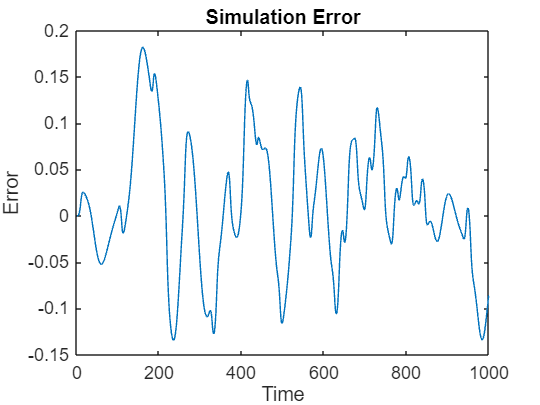

% Compute the simulation error
simulation_error = y - y_hat;
%disp(simulation_error);
% Plot the simulation error
figure;
plot(simulation_error);
title('Simulation Error');
xlabel('Time');
ylabel('Error');

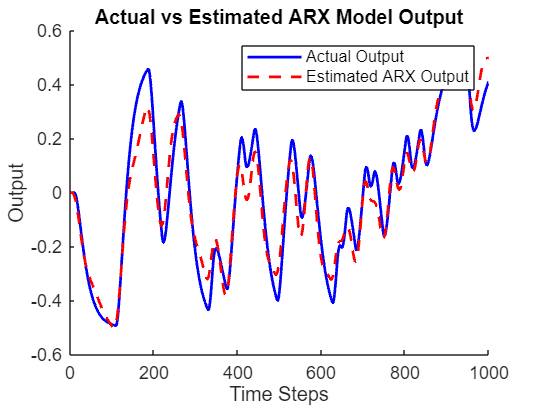


figure;
hold on;
plot(y, 'b', 'LineWidth', 1.5);  % Actual output
plot(y_hat, 'r--', 'LineWidth', 1.5);  % Estimated output
hold off;
title('Actual vs Estimated ARX Model Output');
xlabel('Time Steps');
ylabel('Output');
legend('Actual Output', 'Estimated ARX Output');

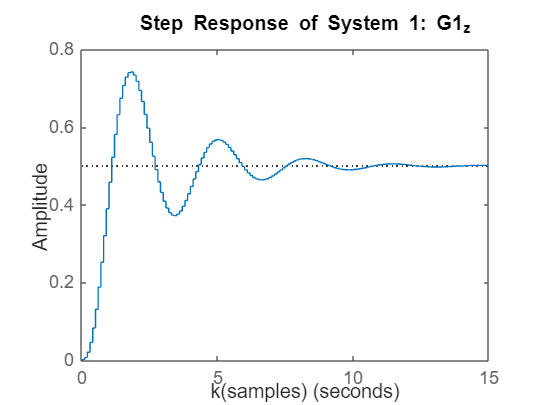

% Apply recursive filtering
[uF, yF] = recursive_filtering(u, y, theta, na, nb, nk);

% Plot filtered signals
figure;
subplot(2, 1, 1);
plot(uF);
title('Filtered Input Signal');
xlabel('k');
ylabel('Input');

subplot(2, 1, 2);
plot(yF);
title('Filtered Output Signal');
xlabel('k');
ylabel('Output');

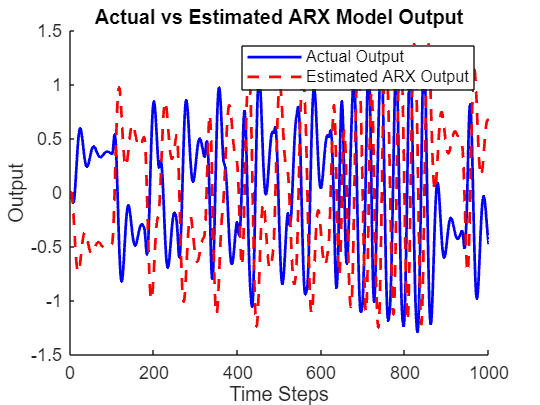

figure;
hold on;
plot(yF, 'b', 'LineWidth', 1.5);  % Actual output
plot(y_hat, 'r--', 'LineWidth', 1.5);  % Estimated output
hold off;
title('Actual vs Estimated ARX Model Output');
xlabel('Time Steps');
ylabel('Output');
legend('Actual Output', 'Estimated ARX Output');

% Compute the Instrumental Variables matrix Z
Z = instrumental_variables(u, y_hat, na, nb);

% Display the Instrumental Variables matrix Z
disp('Instrumental Variables Matrix Z:');

Instrumental Variables Matrix Z:


disp(Z);

   -1.0000   -1.0000   -1.0000    0.0076         0         0
   -1.0000   -1.0000   -1.0000    0.0265    0.0076         0
   -1.0000   -1.0000   -1.0000    0.0578    0.0265    0.0076
   -1.0000   -1.0000   -1.0000    0.1010    0.0578    0.0265
   -1.0000   -1.0000   -1.0000    0.1545    0.1010    0.0578
   -1.0000   -1.0000   -1.0000    0.2162    0.1545    0.1010
   -1.0000   -1.0000   -1.0000    0.2832    0.2162    0.1545
   -1.0000   -1.0000   -1.0000    0.3530    0.2832    0.2162
   -1.0000   -1.0000   -1.0000    0.4227    0.3530    0.2832
   -1.0000   -1.0000   -1.0000    0.4898    0.4227    0.3530
   -1.0000   -1.0000   -1.0000    0.5519    0.4898    0.4227
   -1.0000   -1.0000   -1.0000    0.6071    0.5519    0.4898
   -1.0000   -1.0000   -1.0000    0.6538    0.6071    0.5519
   -1.0000   -1.0000   -1.0000    0.6909    0.6538    0.6071
   -1.0000   -1.0000   -1.0000    0.7177    0.6909    0.6538
   -1.0000   -1.0000   -1.0000    0.7339    0.7177    0.6909
   -1.0000   -1.0000   -

y_z = y_hat(na+1:end);

% Compute the IV estimate of parameters
theta_IV = (Z' * X) \ (Z' * y_z);

% Display the IV estimated parameters
disp('IV Estimated Parameters:');

IV Estimated Parameters:


disp(theta_IV);

    0.0121
    0.0067
   -0.0003
   -4.0571
    4.4733
   -1.3678



% Generate the regression matrix
X_FIR = fir(u, 200);

% Display the regression matrix
disp('Regression Matrix X_FIR:');

Regression Matrix X_FIR:


disp(X_FIR);

    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    

% Estimating Paratmeters using Least squares method
y_fir = y(201:end);
theta_FIR = (X_FIR' * X_FIR) \ X_FIR' * y_fir;
%disp(theta_FIR);

% Compute the FIR model output
y_FIR = fir_model_output(u, theta_FIR, 200);

% Display the estimated output
disp('Estimated FIR Model Output:');

Estimated FIR Model Output:


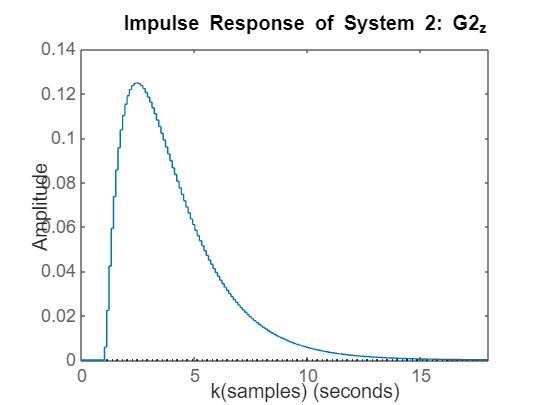

%disp(y_FIR);

% Plot the actual vs estimated output for comparison
figure;
hold on;
plot(y, 'b', 'LineWidth', 1.5);  % Actual output
plot(y_FIR, 'r--', 'LineWidth', 1.5);  % Estimated output
hold off;
title('Actual vs Estimated FIR Model Output');
xlabel('Time Steps');
ylabel('Output');
legend('Actual Output', 'Estimated FIR Output');

% Call the optimization function
theta_opt = optimize_oe(u, y, na, nb, nk, theta);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>



% Display optimized parameters
disp('Optimized Parameters:');

Optimized Parameters:


disp(theta_opt);

    0.0005
    0.0029
    0.0042
   -2.4845
    2.0529
   -0.5532



% Calculate RMSE
rmse_ARX = sqrt(sum((y - y_hat).^2) / length(y));  % RMSE calculation
rmse_FIR = sqrt(sum((y - y_FIR).^2) / length(y));  % RMSE calculation 
rmse_OE = sqrt(sum((y - y_hat).^2) / length(y));  % RMSE calculation  
% Display RMSE
fprintf('RMSE: %.4f\n', rmse_ARX);

RMSE: 0.0888


fprintf('RMSE: %.4f\n', rmse_FIR);

RMSE: 0.2605


fprintf('RMSE: %.4f\n', rmse_OE);

RMSE: 1.0801
